% Carica un'immagine di esempio in scala di grigi
I = imread('peppers.png');
I = im2double(I);

% Parametri del rumore a bande
amplitude = 0.5;
frequency = 50;
[rows, cols, ~] = size(I);
[yGrid, ~] = meshgrid(1:cols, 1:rows);
stripe_pattern = amplitude * sin(2 * pi * frequency * yGrid / rows);

I_noisy = zeros(size(I));
for c = 1:3
    I_noisy(:,:,c) = mat2gray(I(:,:,c) + stripe_pattern);
end

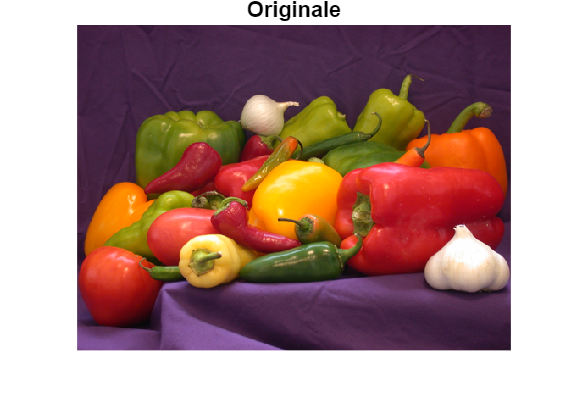

figure;
imshow(I), title('Originale');

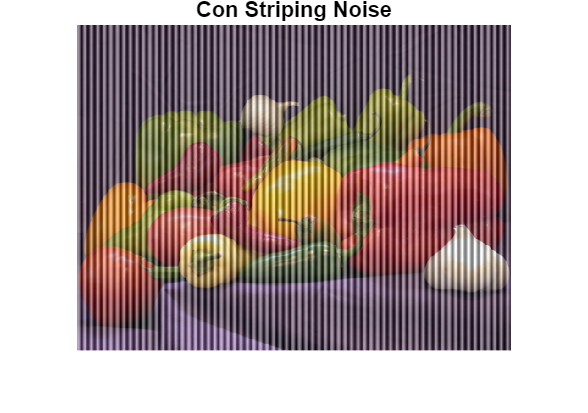

figure;
imshow(I_noisy), title('Con Striping Noise');

kernel_size = 3;
sigma = 1;

lowpass_gaussian = fspecial('gaussian', kernel_size, sigma);
impulse = zeros(kernel_size);
impulse(ceil(kernel_size/2), ceil(kernel_size/2)) = 1;
highpass_gaussian = impulse - lowpass_gaussian;

I_highpass = zeros(size(I));
I_lowpass = zeros(size(I));
for c = 1:3
    I_highpass(:,:,c) = imfilter(I(:,:,c), highpass_gaussian, 'replicate');
    I_lowpass(:,:,c)  = imfilter(I(:,:,c), fspecial('average', [3 3]), 'replicate');
end

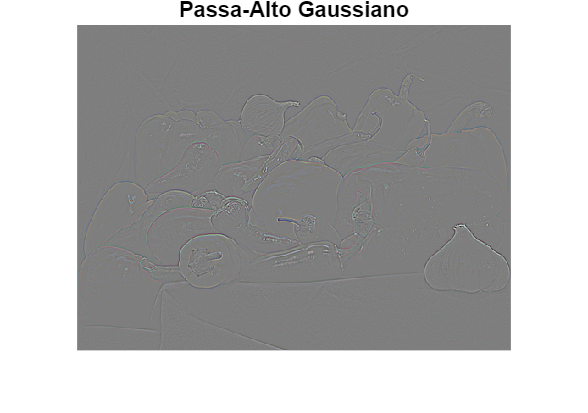

% Visualizzazioni
figure;
imshow(mat2gray(I_highpass)), title('Passa-Alto Gaussiano');

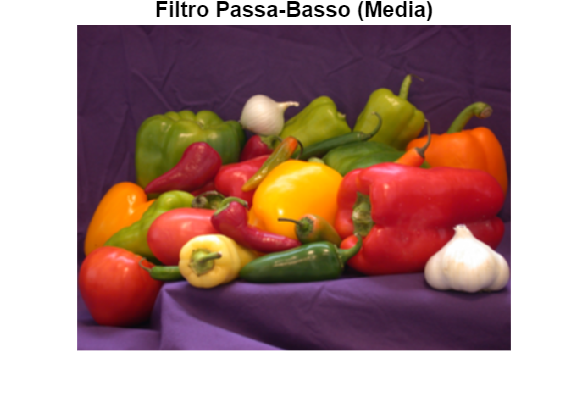


figure;
imshow(I_lowpass), title('Filtro Passa-Basso (Media)');

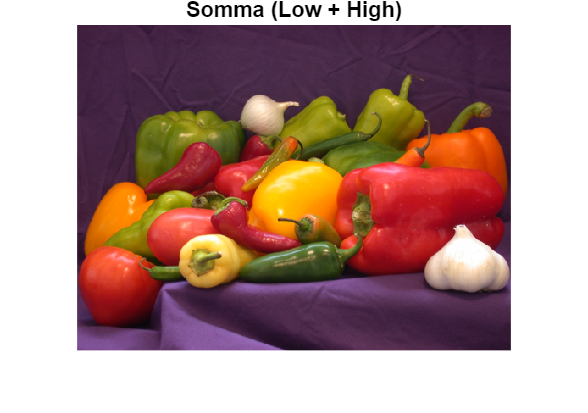

% Somma dei risultati
I_sum = I_highpass + I_lowpass;

figure;
imshow(mat2gray(I_sum)), title('Somma (Low + High)');